compare spectral coherency data

%load spectral coherency data
load ('C:\Users\Orsborn Lab\OneDrive - UW\projects\Brain EEG\data\180328\figures\20190904\180328_specCoh_ECOG_gridMeanSsubtracted_SC32_100trials_Sept4.mat')


Then we spit out the coherency matrices

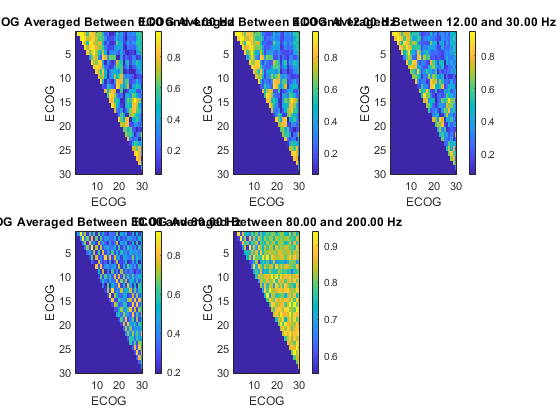

freqRange_all = [0 4;4 12;12 30;30 80;80 200];
perIndex = 99;

electrode_range = 1:30;

%extract the information
cohSeq_ECOG = cohDat(1).coh; %1 for ECOG32
cohSeq_SC32 = cohDat(2).coh; %2 for SC32
cohSeq_ECOG_SC32 = cohDat(3).coh; %3 interDrive spectral coherency

for fi = 1:size(freqRange_all,1)
    
    %averaging the frequency components
    freqRange = freqRange_all(fi,:);
    freqRangeIndex  = cal_index_freq(specDat(1).freq ,freqRange(1),freqRange(2));
    cohSeq_fr_ECOG = mean(cohSeq_ECOG(:,:,freqRangeIndex),3);
    cohSeq_fr_SC32 = mean(cohSeq_SC32(:,:,freqRangeIndex),3);
    cohSeq_fr_ECOG_SC32 = mean(cohSeq_ECOG_SC32(:,:,freqRangeIndex),3);
    
    %plotting
    subplot(2,3,fi)
    imagesc(cohSeq_fr_ECOG(electrode_range,electrode_range))
    title(sprintf('ECOG Averaged Between %0.2f and %0.2f Hz',freqRange(1),freqRange(2)))
    ylabel('ECOG')
    xlabel('ECOG')
    colorbar

end

Now we look at the L_matrices,  we copy the code from 

load('C:\Users\Orsborn Lab\OneDrive - UW\projects\Brain EEG\data\180328\figures\20190916\180328_specCoh_ECOG_gridMeanSsubtracted_SC32_100trials_learned graph signal_Sept17.mat')

num_iter = 5; % number of max iterations
%iniitial setup

alpha = 0.1;
beta = 1;

n_nodes = 30;
%first 61 electrodes for now
X_test = a_coefficients_electrodes(1:n_nodes,:);
Y0 = X_test;

n_data = size(X_test,2);

M = full(DuplicationM(n_nodes));

%initialize parameters
Y = Y0;
vechL_0.vechL = ones(n_nodes * (n_nodes + 1) / 2, 1);
Y_0.Y_opt = zeros([n_nodes,n_data]);

[L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.500000e+04.

Finished 1 iteration with 2.04  and 1.02
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opti

L_iter_alphas(:,:,1) = L_iter;

alpha = 1;
[L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.500000e+04.

Finished 1 iteration with 2.04  and 1.12
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opti

L_iter_alphas(:,:,2) = L_iter;

% try a different alpha
alpha = 10;
[L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>
Finished 1 iteration with -15.80  and -8.14
Solving problem using fmincon.

<a href 

L_iter_alphas(:,:,3) = L_iter;

% try a different alpha
alpha = 30;
[L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
Finished 1 iteration with 1.08  and 10.78
Solving problem using fmincon.

Solver stopped prematurely.

fmincon

L_iter_alphas(:,:,4) = L_iter;

Plotted out the alphas

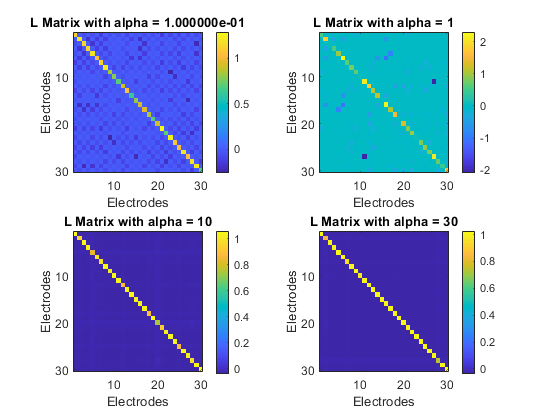

figure

alphas = [0.1 1 10 30];
for alpha_i = 1:length(alphas)
    subplot(2,2,alpha_i)
    imagesc(squeeze(L_iter_alphas(:,:,alpha_i)))
    title(sprintf('L Matrix with alpha = %d',alphas(alpha_i)))
    xlabel('Electrodes')
    ylabel('Electrodes')
    colorbar
end  

Comparing this figure to the one generated by spectral coherency figure,   we don't see qualitatively similarities between these two figures. However the checker board pattern is quite similar to the gamma band structures. 

Now, let's see if we can include other AR coefficients

alpha = 0.1;
beta = 1;

n_nodes = 30;
starting_AR_coeff = 2;
%first 61 electrodes for now
X_test = a_coefficients_electrodes(1:n_nodes,starting_AR_coeff:end);
Y0 = X_test;

n_data = size(X_test,2);

M = full(DuplicationM(n_nodes));

%initialize parameters
Y = Y0;
vechL_0.vechL = ones(n_nodes * (n_nodes + 1) / 2, 1);
Y_0.Y_opt = zeros([n_nodes,n_data]);


alphas = [0.1 1 10 30];

for alpha_i = 1:length(alphas)
    alpha = alphas(alpha_i)
    [L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);
    L_iter_alphas_AR(:,:,alpha_i) = L_iter;
end  

alpha = 0.1000


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.200000e+04.

Finished 1 iteration with 2.02  and 1.01
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opti

alpha = 1


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.200000e+04.

Finished 1 iteration with 2.04  and 1.10
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opti


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.200000e+04.

Finished 3 iteration with 2292476672495104.00  and 2292487933795141.00
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
option


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Problem appears unbounded.

fminunc stopped because the objective function value is less than
or equal to the value of the objective function limit.

<stopping criteria details>
Finished 5 iteration with -6332000451929851297792.00  and -6332000451769591136256.00

alpha = 10


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.200000e+04.

Finished 1 iteration with 4.06  and 10.38
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opt

alpha = 30


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.200000e+04.

Finished 1 iteration with 1.85  and 10.16
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opt

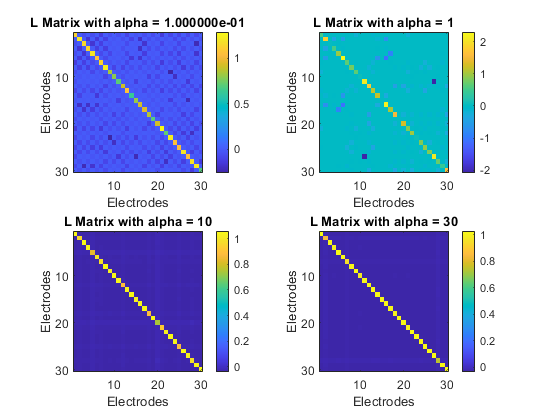

figure

for alpha_i = 1:length(alphas)
    subplot(2,2,alpha_i)
    imagesc(squeeze(L_iter_alphas_AR(:,:,alpha_i)))
    title(sprintf('L Matrix with alpha = %d',alphas(alpha_i)))
    xlabel('Electrodes')
    ylabel('Electrodes')
    colorbar
end  

next we figure out how to draw L matrix figures.

one idea would be to normalize with respect to the diagnal elements

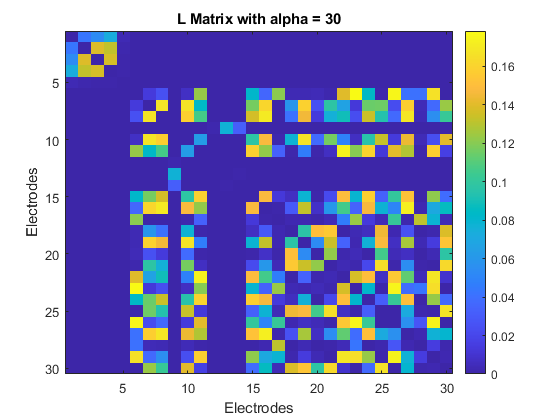

L_iter_display =  L_iter;


n_rows = size(L_iter_display,1);
L_iter_display(find(eye(size(L_iter_display)))) = 0;

%L_iter_display = - 1 * L_iter_display ./ repmat(diag(L_iter_display),1,n_rows);


figure
imagesc(squeeze(-L_iter_display))
title(sprintf('L Matrix with alpha = %d',alphas(alpha_i)))
xlabel('Electrodes')
ylabel('Electrodes')
%caxis([0 0.1])
colorbar

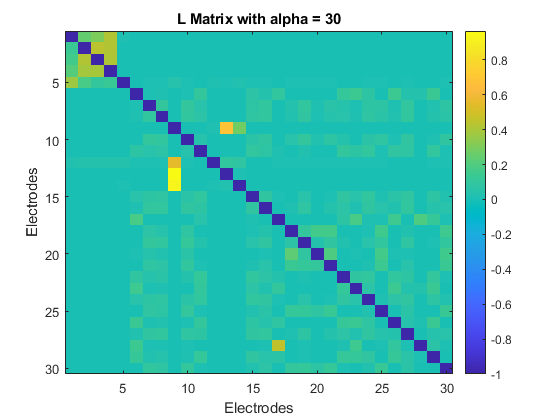

L_iter_display =  L_iter;


n_rows = size(L_iter_display,1);
%L_iter_display(find(eye(size(L_iter_display)))) = 0;

L_iter_display = - 1 * L_iter_display ./ repmat(diag(L_iter_display),1,n_rows);


figure
imagesc(squeeze(L_iter_display))
title(sprintf('L Matrix with alpha = %d',alphas(alpha_i)))
xlabel('Electrodes')
ylabel('Electrodes')
%caxis([0 0.1])
colorbar

while this just does not make sense anymore, we lose symmetry around the diagnal! 